# **Case Study Newton-Raphson ****Method**

This livescript demonstrates how to use the Newton-Raphson method to find the roots of a function. The roots of a function are the values of the input for which the output is 0. The Newton-Raphson method iteratively produces better approximations for the root of a function. The Newton-Raphson method:


$$x_{n+1} = x_n - \frac{f(x_n)}{f'(x_n)}$$


uses the current approximation of the root $x_n$, the value of the function at that point $f(x_n)$, and the derivative of the function $f'(x_n)$ to output a new approximation of the root $x_{n+1}$.

As an example, here the function: 


$$f(x) =  x^4 + 4x^3 + 4x^2 + 0.5x - 0.1$$
 

will be used. It has a derivative:


$$
f'(x) =  4x^3 + 12x^2 + 8x + 0.5;
$$


The function and the derivative are written as MATLAB functions at the bottom of this script. First, we will plot the function to see what it looks like:

x = -3:0.01:1

x =    -3.0000   -2.9900   -2.9800   -2.9700   -2.9600   -2.9500   -2.9400   -2.9300   -2.9200   -2.9100   -2.9000   -2.8900   -2.8800   -2.8700   -2.8600   -2.8500   -2.8400   -2.8300   -2.8200   -2.8100   -2.8000   -2.7900   -2.7800   -2.7700   -2.7600   -2.7500   -2.7400   -2.7300   -2.7200   -2.7100   -2.7000   -2.6900   -2.6800   -2.6700   -2.6600   -2.6500   -2.6400   -2.6300   -2.6200   -2.6100   -2.6000   -2.5900   -2.5800   -2.5700   -2.5600   -2.5500   -2.5400   -2.5300   -2.5200   -2.5100


y = f(x)

y =     7.4000    7.1672    6.9387    6.7146    6.4947    6.2790    6.0675    5.8601    5.6567    5.4574    5.2621    5.0707    4.8832    4.6995    4.5196    4.3435    4.1711    4.0023    3.8372    3.6756    3.5176    3.3631    3.2120    3.0643    2.9199    2.7789    2.6412    2.5067    2.3753    2.2472    2.1221    2.0001    1.8811    1.7652    1.6521    1.5420    1.4347    1.3303    1.2287    1.1298    1.0336    0.9401    0.8492    0.7609    0.6752    0.5920    0.5113    0.4330    0.3571    0.2837


plot(x, y)
xlabel("x")
ylabel("f(x)")
grid

As an initial guess for the location of the root we will use 0.2. Since the Newton-Raphson method only iteratively approaches the true root, it will never find exactly the value of the root. Hence, a tolerance is defined, and we search for a point that is within the tolerance range of the root.

tol = 0.001;   % target tolerance

x0 = 0.2;           % initial guess
y0 = f(x0)          % f(x) at x0 0.1936

y0 = 0.1936

grad = f_prime(x0)  % gradient at x0 is 2.6120 

grad = 2.6120

Since we do not know how many times we will have to improve our guess for the root, a while loop will be used in place of a for loop. Note, this could cause an issue of the root cannot be found, as the code could run forever.

x = x0;        % initialise x

while (f(x) > tol)
    y = f(x);
    grad = f_prime(x);
    x = x - y/grad
end

x = 0.1259

x = 0.1056

x = 0.1041


x    % final approximate value of root

x = 0.1041

f(x) % value of function at root

ans = 1.2414e-05

Adding the approximate root to the plot:

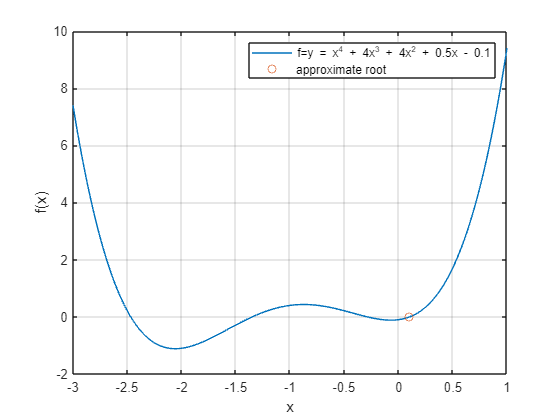

hold on % to plot onto same figure
scatter(x, f(x))
legend(["f=y = x^4 + 4x^3 + 4x^2 + 0.5x - 0.1", "approximate root"])

function y = f(x)
    y = x.^4 + 4.*x.^3 + 4.*x.^2 + 0.5.*x - 0.1;
end

function dydx = f_prime(x)
    dydx = 4*x^3 + 12*x^2 + 8*x + 0.5;y = x.^4 + 4.*x.^3 + 4.*x.^2 + 0.5.*x - 0.1;
end